## **Pnömoni Tespiti — CNN ile Görüntü Sınıflandırma**

### **1. Veri Hazırlığı**

### **1.1 Ortam Hazırlığı ve Dataset Kontrolü**

Bu bölümde çalışma ortamını hazırlayıp dataset klasörünün doğru konumda olduğunu kontrol ediyoruz. Dataset, NORMAL ve PNEUMONIA olmak üzere iki sınıfa ayrılmış chest X-ray görüntülerinden oluşmaktadır.

% Workspace temizleme
clear; clc; close all;

% Dataset yolunu tanımla (göreceli yol — repo içinde)
datasetPath = fullfile(pwd, 'data', 'chest_xray');

% Klasörün var olup olmadığını kontrol et
if exist(datasetPath, 'dir')
    fprintf('Dataset klasörü bulundu: %s\n', datasetPath);
    
    % Alt klasörleri listele
    subFolders = dir(datasetPath);
    subFolders = subFolders([subFolders.isdir] & ~ismember({subFolders.name}, {'.', '..'}));
    
    fprintf('\nAlt klasörler:\n');
    for i = 1:length(subFolders)
        fprintf('  - %s\n', subFolders(i).name);
    end
else
    error('Dataset klasörü bulunamadı! Yolu kontrol et: %s', datasetPath);
end

Dataset klasörü bulundu: C:\Users\ferit\OneDrive\Belgeler\MATLAB\image-data-presentation\data\chest_xray



Alt klasörler:


  - test
  - train
  - val


### **1.2 Sınıf Dağılımı ve Görüntü Sayısı**

Bu bölümde train, val ve test setlerindeki NORMAL ve PNEUMONIA sınıflarına ait görüntü sayılarını sayıyoruz. Bu analiz hem dataset boyutunu görmek hem de sınıf dengesizliğini tespit etmek açısından önemlidir.

% Her set için sınıf bazında görüntü sayılarını hesapla
sets = {'train', 'val', 'test'};
classes = {'NORMAL', 'PNEUMONIA'};

% Sonuçları saklamak için tablo oluştur
counts = zeros(length(sets), length(classes));

fprintf('Dataset Sınıf Dağılımı:\n');

Dataset Sınıf Dağılımı:


fprintf('-------------------------------------\n');

-------------------------------------


fprintf('%-10s %-10s %-12s %-8s\n', 'Set', 'NORMAL', 'PNEUMONIA', 'Toplam');

Set        NORMAL     PNEUMONIA    Toplam  


fprintf('-------------------------------------\n');

-------------------------------------



for i = 1:length(sets)
    for j = 1:length(classes)
        folderPath = fullfile(datasetPath, sets{i}, classes{j});
        files = dir(fullfile(folderPath, '*.jpeg'));
        counts(i, j) = length(files);
    end
    fprintf('%-10s %-10d %-12d %-8d\n', sets{i}, counts(i,1), counts(i,2), sum(counts(i,:)));
end

train      1341       3875         5216    
val        8          8            16      
test       234        390          624     



fprintf('-------------------------------------\n');

-------------------------------------


fprintf('%-10s %-10d %-12d %-8d\n', 'TOPLAM', sum(counts(:,1)), sum(counts(:,2)), sum(counts(:)));

TOPLAM     1583       4273         5856    


Çıktıdan iki önemli gözlem yapılabilir. Birincisi, dataset toplam 5856 görüntü içermekte olup train setinin (5216) val setine (16) göre orantısız büyüklükte olması dikkat çekicidir; bu nedenle val setini sonradan train'den ayıracağımız bir kısımla genişletmemiz gerekecek. İkincisi, PNEUMONIA sınıfı NORMAL sınıfının yaklaşık 2.7 katı kadar görüntü içermekte; bu sınıf dengesizliği modelin eğitiminde ele alınması gereken kritik bir problemdir.Çıktıdan iki önemli gözlem yapılabilir. Birincisi, dataset toplam 5856 görüntü içermekte olup train setinin (5216) val setine (16) göre orantısız büyüklükte olması dikkat çekicidir; bu nedenle val setini sonradan train'den ayıracağımız bir kısımla genişletmemiz gerekecek. İkincisi, PNEUMONIA sınıfı NORMAL sınıfının yaklaşık 2.7 katı kadar görüntü içermekte; bu sınıf dengesizliği modelin eğitiminde ele alınması gereken kritik bir problemdir.

### 1.3 Örnek Görüntülerin İncelenmesi

Veriyi modele vermeden önce her sınıftan örnek görüntüleri inceliyoruz. NORMAL ve PNEUMONIA sınıfları arasındaki radyolojik farkları gözlemlemek, hem datasetin doğasını anlamak hem de modelin neyi öğrenmesi gerektiğini görmek açısından önemlidir.

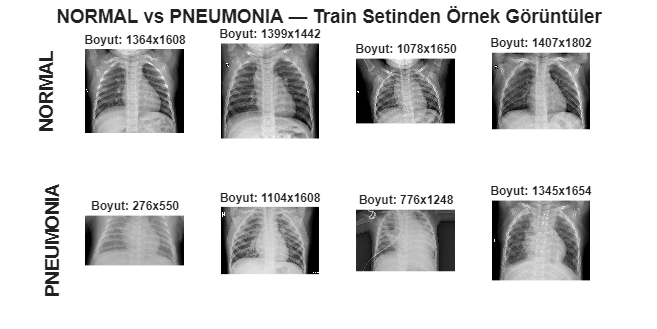

% Train setinden her sınıftan rastgele 4 örnek görüntü göster
figure('Position', [100 100 1200 600], 'Color', 'w');

classes = {'NORMAL', 'PNEUMONIA'};
numSamples = 4;

for c = 1:length(classes)
    folderPath = fullfile(datasetPath, 'train', classes{c});
    files = dir(fullfile(folderPath, '*.jpeg'));
    
    % Rastgele 4 görüntü seç
    rng(42); % tekrar üretilebilirlik için
    randomIdx = randperm(length(files), numSamples);
    
    for s = 1:numSamples
        subplot(2, numSamples, (c-1)*numSamples + s);
        img = imread(fullfile(folderPath, files(randomIdx(s)).name));
        imshow(img);
        
        if s == 1
            ylabel(classes{c}, 'FontSize', 14, 'FontWeight', 'bold');
        end
        
        title(sprintf('Boyut: %dx%d', size(img,1), size(img,2)), 'FontSize', 9);
    end
end

sgtitle('NORMAL vs PNEUMONIA — Train Setinden Örnek Görüntüler', 'FontSize', 14, 'FontWeight', 'bold');

Görüntüler incelendiğinde NORMAL akciğerlerin daha temiz ve net hava boşluklarına sahip olduğu, PNEUMONIA görüntülerinde ise akciğer alanlarında bulanık beyaz lekeler ve yoğunlaşmalar (konsolidasyon) bulunduğu gözlemlenmektedir. Ayrıca görüntülerin farklı boyutlarda olduğu görülmekte; bu nedenle modele vermeden önce hepsini sabit bir boyuta yeniden ölçeklemek gerekecektir.

### 1.4 Sınıf Dağılımının Görselleştirilmesi

Sınıf dağılımını grafik üzerinde göstererek dengesizlik problemini daha net ortaya koyuyoruz. Bu görselleştirme, eğitim sürecinde kullanılacak ağırlıklandırma stratejisinin gerekliliğini somutlaştıracaktır.

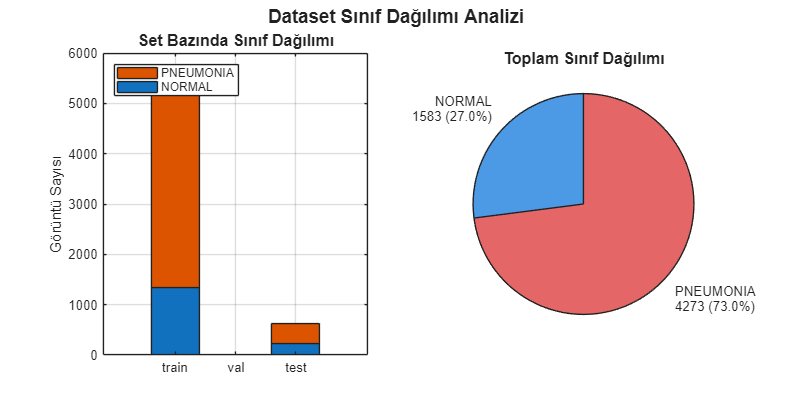

% Sınıf dağılımı bar chart'ı
figure('Position', [100 100 1000 500], 'Color', 'w');

% Train, val, test için stacked bar chart
subplot(1, 2, 1);
bar(counts, 'stacked');
set(gca, 'XTickLabel', sets);
ylabel('Görüntü Sayısı', 'FontSize', 11);
title('Set Bazında Sınıf Dağılımı', 'FontSize', 12, 'FontWeight', 'bold');
legend({'NORMAL', 'PNEUMONIA'}, 'Location', 'northwest');
grid on;

% Toplam dağılım pie chart
subplot(1, 2, 2);
totalCounts = [sum(counts(:,1)), sum(counts(:,2))];
labels = {sprintf('NORMAL\n%d (%.1f%%)', totalCounts(1), 100*totalCounts(1)/sum(totalCounts)), ...
          sprintf('PNEUMONIA\n%d (%.1f%%)', totalCounts(2), 100*totalCounts(2)/sum(totalCounts))};
pie(totalCounts, labels);
title('Toplam Sınıf Dağılımı', 'FontSize', 12, 'FontWeight', 'bold');
colormap([0.3 0.6 0.9; 0.9 0.4 0.4]);

sgtitle('Dataset Sınıf Dağılımı Analizi', 'FontSize', 14, 'FontWeight', 'bold');

Grafiklerden de anlaşılacağı üzere PNEUMONIA sınıfı toplam dataset'in %73'ünü, NORMAL sınıfı ise yalnızca %27'sini oluşturmaktadır. Bu dengesizlik, hiçbir önlem alınmadığında modelin "hep PNEUMONIA tahmin et" gibi kestirme bir strateji geliştirmesine ve görünürde yüksek accuracy elde etmesine rağmen NORMAL örneklerde başarısız olmasına yol açabilir. Bu nedenle eğitim aşamasında sınıf ağırlıklandırma (class weighting) yöntemini uygulayacağız.